load mtlb

% alpha: y(n)=x(n)+alpha*x(n−delta)
timelag = 0.23;
delta = round(Fs*timelag);
alpha = 0.5;

orig = [mtlb;zeros(delta,1)];
echo = [zeros(delta,1);mtlb]*alpha;

mtEcho = orig + echo;

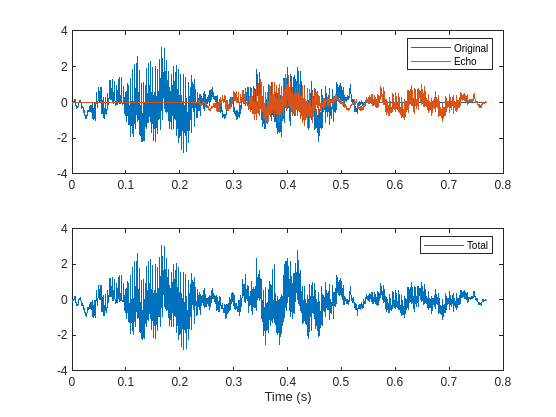

t = (0:length(mtEcho)-1)/Fs;

subplot(2,1,1)
plot(t,[orig echo])
legend('Original','Echo')

subplot(2,1,2)
plot(t,mtEcho)
legend('Total')
xlabel('Time (s)')

% uncomment to hear echo
% soundsc(mtEcho,Fs)

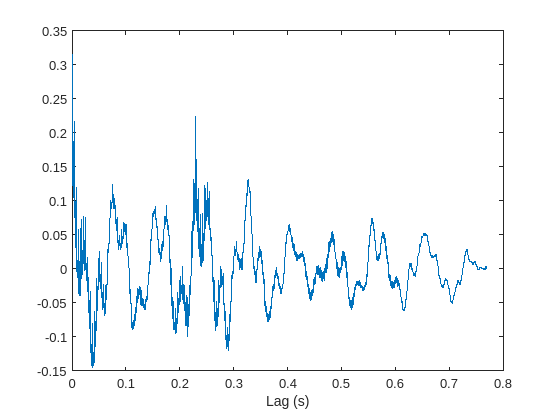

[Rmm,lags] = xcorr(mtEcho,'unbiased');

Rmm = Rmm(lags>0);
lags = lags(lags>0);

figure
plot(lags/Fs,Rmm)
xlabel('Lag (s)')

[~,dl] = findpeaks(Rmm,lags,'MinPeakHeight',0.22);

mtNew = filter(1,[1 zeros(1,dl-1) alpha],mtEcho);

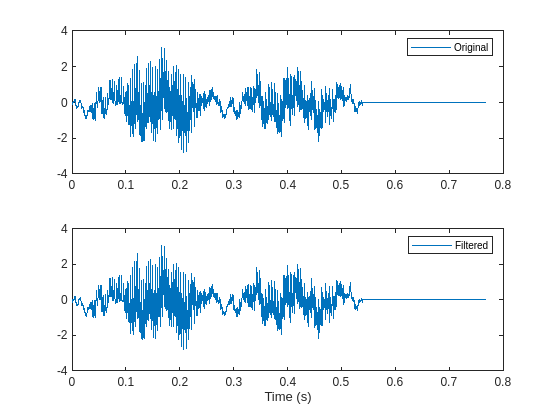

subplot(2,1,1)
plot(t,orig)
legend('Original')

subplot(2,1,2)
plot(t,mtNew)
legend('Filtered')
xlabel('Time (s)')

% To hear new w/o echo, uncomment
% % soundsc(mtNew,Fs)